# Script di testing della classe filtro notch che poi viene utilizzata nei controllori

clc
close all
clear all

st = 0.001; %tempo di campionamento
wn = 223;   %omega del filtro
xci_z=0.1;  %aggiustate xci_z e xci_p per rendere il filtro più o meno selettivo
xci_p=0.7;
s=tf('s');
%filtro notch in continua
Fns=(s^2+2*xci_z*wn*s+wn^2)/(s^2+2*xci_p*wn*s+wn^2)

Fns =
 
  s^2 + 44.6 s + 49729
  ---------------------
  s^2 + 312.2 s + 49729
 
Continuous-time transfer function.
Model Properties


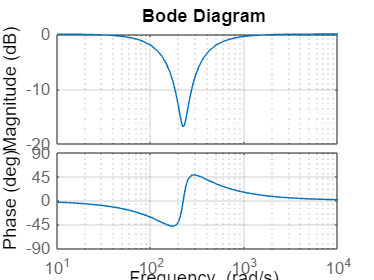

bode(Fns)
grid on 


%filtro notch in discreto
Fnz = c2d(Fns,0.001,'tustin');
%print dei paramteri per conferma della classe
numC0d=Fnz.Numerator{1}

numC0d =     0.8855   -1.6903    0.8473


denC0d=Fnz.Denominator{1}

denC0d =     1.0000   -1.6903    0.7328



% y = A*y(k-x)+B*u(k-x)
filtro = FilterNotch(st,wn,xci_z,xci_p)

filtro =   FilterNotch with properties:

           st: 1.0000e-03
           wn: 223
        xci_p: 0.7000
        xci_z: 0.1000
        nu_fn: 0.8855
      num1_fn: -1.6903
      num2_fn: 0.8473
        ny_fn: 1
      nym1_fn: -1.6903
      nym2_fn: 0.7328
          um1: 0
          um2: 0
    um1_notch: 0
    um2_notch: 0

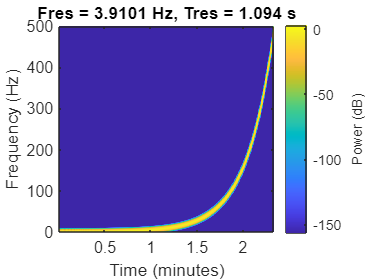

filtro.starting(0);

%generazione di un seganel chirp per scorrere tutte le frequenze e vedere
%l'attenuazione del segnale in uscita
t=(0:st:140)';
w0=1; %rad/s
w1=pi/st; %rad/s     Fs=1/Ts, Ws=2*pi/Ts, 0.5*Ws=pi/Ts -> valore alto tipo val max dato
input = chirp(t,w0/2/pi,t(end),w1/2/pi, 'logarithmic');
figure
pspectrum(input,1/st,'spectrogram');

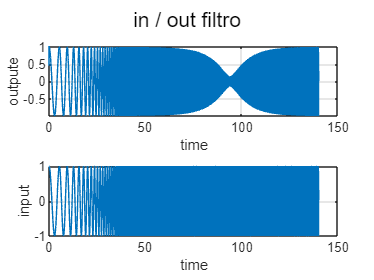


output=zeros(length(t),1);
for idx=1:length(t)
    output(idx,:)=filtro.computeAction(input(idx));
end

%plot nel tempo dei risultati
figure(1)
subplot(2,1,1)
plot(t,output(:))
xlabel('time')
ylabel('outpute')
grid on

subplot(2,1,2)
plot(t,input)
xlabel('time')
ylabel('input')
grid on

sgtitle('in / out filtro')

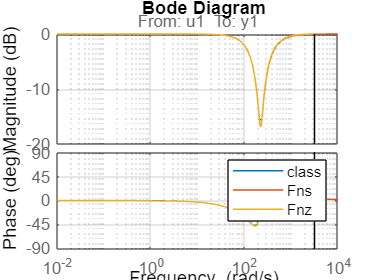


identification=iddata(output(:),input,st);
freq_resp_ident = spafdr(identification);
figure
bode_opts = bodeoptions('cstprefs');
bode_opts.PhaseWrapping = 'on';
h=bodeplot(freq_resp_ident, bode_opts);
grid on
hold on
bode(Fns)
bode(Fnz)
legend('class','Fns','Fnz')
hold off